# 2 DOF Cell Model in plane strain

## Data

% 
clearvars; close all; clc;
set_env;
addpath("Functions and Scripts\");
addpath("2DOF\");
load('cell_2dof.mat')
load('cell_2dof_pstrain.mat')

%

% Data --------------------------------------------------------------
epsilon1_max = 0.05;

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 l_c w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F C(x) 

syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)

## Equations

% Equations ---------------------------------------------------------
makeassumptions
% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / (l_0 - l_c) == (dtf / 2) / (l_0 - l_c - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-l_{c}-\xi +\xi_{0}\right)}{l_{0}-l_{c}}$$

t_f(x) = tf_0 + dt_f;
limit(t_f(x), l_c, l_0)

$$ans = \left\{ \begin{array}{cl} x & \text{ if }{\mathrm{tf}}_{0}=x\vee \xi =\xi_{0} \end{array}\right.$$


w = pstrain_2dof.w

$$w = w_{0}$$

t_p = pstrain_2dof.t_p

$$t\_p = {\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)$$

l_a = pstrain_2dof.l_a

$$l\_a = l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}$$

A1 = pstrain_2dof.A1

$$A1 = l_{c}\,w_{0}$$

A2 = pstrain_2dof.A2

$$A2 = w_{0}\,\left(l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)$$

C1_str = pstrain_2dof.C1

$$C1\_str = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$

C2_str = pstrain_2dof.C2

$$C2\_str = \frac{\log\left(-\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-l_{c}\right)-\epsilon_{p}\,l_{c}\,\left({\mathrm{tf}}_{0}-x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\epsilon_{f}\,l_{0}\,w_{0}\,\epsilon_{1}\left(x\right)-\epsilon_{f}\,l_{c}\,w_{0}\,\epsilon_{1}\left(x\right)\right)}{{\mathrm{tf}}_{0}-x}-\frac{\log\left(\epsilon_{p}\,\left(l_{0}-l_{c}\right)\,\left({\mathrm{tf}}_{0}-x\right)-\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-l_{c}\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\epsilon_{f}\,l_{0}\,w_{0}\,\epsilon_{1}\left(x\right)-\epsilon_{f}\,l_{c}\,w_{0}\,\epsilon_{1}\left(x\right)\right)}{{\mathrm{tf}}_{0}-x}$$

Vol_0 = pstrain_2dof.Vol_0                 

$$Vol\_0 = l_{0}\,{\mathrm{tp}}_{0}\,w_{0}$$


pstrain = sstrain2(pstrain_2dof, "PSTRAIN");
Vol = pstrain.Vol

$$Vol = l_{c}\,{\mathrm{tf}}_{0}\,w_{0}+\frac{w_{0}\,\left({\mathrm{tf}}_{0}+x\right)\,\left(l_{0}-l_{c}\right)}{2}+2\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\,\left(l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)+2\,l_{c}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)$$

C1 = pstrain.C1

$$C1 = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$

C2 = pstrain.C2

$$C2 = \frac{\log\left(-\left(l_{0}-l_{c}\right)\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\right)-\epsilon_{p}\,l_{c}\,\left({\mathrm{tf}}_{0}-x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\frac{\epsilon_{f}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,\left(l_{0}-l_{c}\right)}-\frac{\epsilon_{f}\,l_{c}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)}\right)}{{\mathrm{tf}}_{0}-x}-\frac{\log\left(\epsilon_{p}\,\left(l_{0}-l_{c}\right)\,\left({\mathrm{tf}}_{0}-x\right)-\left(l_{0}-l_{c}\right)\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\frac{\epsilon_{f}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,\left(l_{0}-l_{c}\right)}-\frac{\epsilon_{f}\,l_{c}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)}\right)}{{\mathrm{tf}}_{0}-x}$$

Uel = pstrain.Uel

$$Uel(x) = -\frac{Y_{p}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\,\left(l_{0}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)\,{\left({\mathrm{tf}}_{0}-x\right)}^{4}}{64\,{l_{0}}^{2}\,\left(\nu^{2}-1\right)\,{\left(l_{0}-l_{c}\right)}^{2}}$$

% pstrain.A1 = l_c * pstrain.w; 
% C1 = (1 / pstrain.Cf1 + 2 / (pstrain.A1 * epsilon_p / pstrain.t_p))^(-1)
% makeassumptions
% fprintf("C1 as x -> tf_0 \n")
% simplify(limit(C1, x, tf_0))
% fprintf("C1 as l_c -> l_0 \n")
% simplify(limit(C1, l_c, l_0))
% fprintf("C1 as l_c -> 0 \n")
% simplify(limit(C1, l_c, 0))
% 
% C2 = simplify(pstrain.C2)
% makeassumptions
% fprintf("C2 as x -> tf_0 \n")
% simplify(limit(sstrain2(C2), x, tf_0))
% fprintf("C2 as l_c -> l_0 \n")
% simplify(limit(sstrain2(C2), l_c, l_0))
% fprintf("C2 as l_c -> l_0, x -> tf_0 \n")
% simplify(limit(ans, x, tf_0))
% fprintf("C2 as l_c -> 0 \n")
% simplify(limit(sstrain2(C2) , l_c, 0))
% fprintf("C1 1 DOF\n")
% res_1dof_pstrain.C

% myfig(1, "C 1DOF - $C_2$ 2DOF with $l_c$ = 0"); hold on; grid on;
% fplot(x,sdata2(simplify(limit(sstrain2(C2) , l_c, 0))), [double(sdata2(tf_0)) , 10e-3], 'LineWidth', 1.5, 'DisplayName', "$C_2$ 2DOF")
% fplot(x,sdata2(res_1dof_pstrain.C), [double(sdata2(tf_0)) , 10e-3], '--', 'LineWidth', 1.5, 'DisplayName', "C 1DOF")
% legend("Location","northeast")
% title("C 1DOF - $C_2$ 2DOF with $l_c$ = 0")
% xlabel("x [m]")
% ylabel("C(x) [F]")

% Range limit
x_min = sdata2(tf_0)

$$x\_min = \frac{1}{10000}$$

x_max = sdata2(rhs(isolate(sstrain2(epsilon_1(x)) == epsilon1_max, x)))

$$x\_max = \frac{\sqrt{2}\,\sqrt{5}\,\sqrt{40}\,\sqrt{\frac{1}{40}-l_{c}}}{200}+\frac{1}{10000}$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C = C1

$$C = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$


% Min capacitance
Cmin = vpa(sdata2(limit(C, x, x_max)),4)

$$Cmin = -\frac{1.0}{\frac{1.662e+7\,\left(\frac{2.143\,\left(0.01\,l_{c}-0.00025\right)}{l_{c}-0.025}-1.0\right)}{l_{c}}-\frac{4.185e+7}{l_{c}}}$$


% Max capacitance
Cmax = vpa(sdata2(limit(C, x, tf_0)),4)

$$Cmax = 1.71e-8\,l_{c}$$

## Elastic energy

Uel

$$Uel(x) = -\frac{Y_{p}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\,\left(l_{0}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)\,{\left({\mathrm{tf}}_{0}-x\right)}^{4}}{64\,{l_{0}}^{2}\,\left(\nu^{2}-1\right)\,{\left(l_{0}-l_{c}\right)}^{2}}$$

## Equations

eq1 = simplify(vpa(sdata2(diff(Uel,x) - V^2 /2 * diff(C, x) == F), 4));
eq2 = simplify(vpa(sdata2(diff(Uel,l_c) - V^2 /2 * diff(C, l_c) == 0), 4));
% solve(eq2,l_c)

V_range = 0:2500:5000;
x_range = double(linspace(x_min, 1e-3, 20));

sol = cell(length(x_range) * length(V_range), 4);

k = 1;
for i = 1:length(V_range)
    tmpeq2 = subs(eq2, {V, x}, {V_range(i), x_range});
    for j = 1:length(x_range)
        sol_lc = double(solve([pickelem(tmpeq2(x), j), 0 <= l_c <= sdata2(l_0)], l_c, 'Real', true));
        sol_lc = unique(round(sol_lc, 4));
        sol{k,1} = x_range(j); 
        sol{k,2} = V_range(i); 
        if length(sol_lc) > 1
            sol{k,3} = min(sol_lc); 
            sol{k,4} = sort(setdiff(sol_lc, min(sol_lc)));
        elseif length(sol_lc) == 1
            sol{k,3} = sol_lc;
            sol{k,4} = [];
        else
            sol{k,3} = NaN;
            sol{k,4} = [];
        end
        
        k = k + 1;
    end
end


table_sol = cell2table(sol, 'VariableNames', {'x', 'V', 'Main sol.', 'Other sol.'})

table_sol = 60×4 table
        x         V    Main sol.     Other sol. 
    __________    _    _________    ____________

        0.0001    0      0.025      {0×0 double}
    0.00014737    0      0.025      {0×0 double}
    0.00019474    0      0.025      {0×0 double}
    0.00024211    0      0.025      {0×0 double}
    0.00028947    0      0.025      {0×0 double}
    0.00033684    0      0.025      {0×0 double}
    0.00038421    0      0.025      {0×0 double}
    0.00043158    0      0.025      {0×0 double}
    0.00047895    0      0.025      {0×0 double}
    0.00052632    0      0.025      {0×0 double}
    0.00057368    0      0.025      {0×0 double}
    0.00062105    0      0.025      {0×0 double}
    0.00066842    0      0.025      {0×0 double}
    0.00071579    0      0.025      {0×0 double}
    0.00076316    0      0.025      {0×0 double}
    0.0

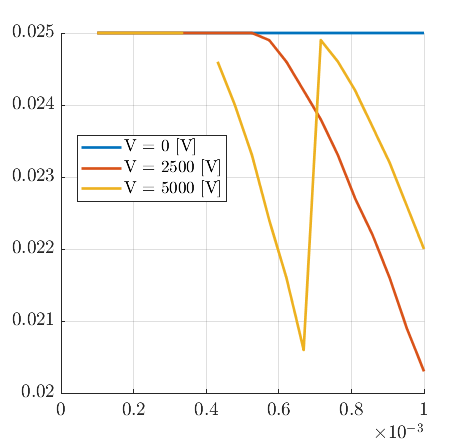



myfig(1, "x - l_c"); hold on
for i = 1:length(V_range)
    lc_V = [sol{(1:length(x_range))*i,3}];
    name = "V = " + num2str(V_range(i)) + " [V]";
    plot(x_range, lc_V, 'LineWidth', 2, 'DisplayName', name)
    legend('Location', 'best')
end

$$eq1(x) = \frac{17803731.66217041015625\,V^{2}\,\left(2.0\,x-0.00019999999999997797317519143689424\right)}{l_{c}\,\left(l_{c}-0.024999999999977262632455676794052\right)\,{\left(\frac{16616816.218017578125\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)}{l_{c}}+\frac{41849759.3638916015625}{l_{c}}\right)}^{2}}-\frac{686813.1868133544921875\,{\left(x-0.000099999999999988986587595718447119\right)}^{3}\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)\,\left(\frac{{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{8.0\,l_{c}-0.19999999999981810105964541435242}-0.024999999999977262632455676794052\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{2}}-\frac{171703.296703338623046875\,{\left(x-0.000099999999999988986587595718447119\right)}^{4}\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)\,\left(2.0\,x-0.00019999999999997797317519143689424\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{2}\,\left(8.0\,l_{c}-0.19999999999981810105964541435242\right)}-\frac{367935.63579273223876953125\,{\left(x-0.000099999999999988986587595718447119\right)}^{4}\,\left(2.0\,x-0.00019999999999997797317519143689424\right)\,\left(\frac{{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{8.0\,l_{c}-0.19999999999981810105964541435242}-0.024999999999977262632455676794052\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{3}}=F$$


% % Plot x - C(x)
% myfig(1,"x - C(x)");
% hold on
% fplot(x, sdata(C(x), 1), [x_min, sdata(x_max)], 'LineWidth', 2)
% xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontWeight','bold')
% hold off
% title("x - C(x)")
% xlabel("x [m]")
% ylabel("C(x) [F]")
% 

## Max voltage

% % Max voltage
% % Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
% Vmax(x) = 2 * t_p / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
% 
% % Plot x - Vmax(x)
% myfig(2,"x - Vmax(x)");
% fplot(x, sdata(Vmax(x), 1), [x_min, sdata(x_max)], 'LineWidth', 2)
% title("$x - V_{max}(x)$")
% xlabel("x [m]")
% ylabel("$V_{max}$(x) [V]")
% 

## Force

% % Force
% Uel(x) = 2 * sdata(1 / 2 * (sigma_1 * epsilon_1) * w * t_p * l, 1)
% 
% F(x,V) = simplify(diff(Uel, x) - V^2 / 2 * diff(sdata(C, 1), x), 500)
% 
% % Min and max force for V = 0 and V = Vmax
% FVmin = vpa(F(x, 0), 4);
% FVmax= vpa(F(x, sdata(Vmax, 1)), 4);

% % Plot x - F(x)
% xtmp = 2e-3:1e-4:2.5e-3;
% [~, idx] = min(real(subs(FVmax, x, xtmp)));
% xstart = xtmp(idx)
% 
% x_range = x_min:1e-4:sdata(x_max);
% FVmin_vec = subs(FVmin,x_range);
% FVmax_vec = real(subs(FVmax,x_range));
% Uel_Fx = double(trapz(x_range, FVmax_vec) - trapz(x_range, FVmin_vec))
% 
% myfig(3,"x - F(x)")
% hold on
% fplot(x, FVmin, [0, 1.2 * sdata(x_max)], 'LineWidth', 1.5)
% fplot(x, FVmax, [0, 1.2 * sdata(x_max)], '--', 'LineWidth', 1.5)
% xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
% xline(sdata(xstart), "--g", "x_{START}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
% hold off
% legend(["$V_{min}$", "$V_{max}$"], "Location", "north")
% title("x - F(x)")
% xlabel("x [m]")
% ylabel("F(x) [N]")
% 

## Q - V

% % Plot Q - V
% C_vec = subs(sdata(C, 1), x_range);
% Vmax_vec = subs(sdata(Vmax, 1), x_range);
% Q_vec = C_vec .* Vmax_vec;
% 
% [V_maxstr_min, idx] = min(Q_vec ./ Cmin);
% x_min_maxstr = x_range(idx);
% 
% [V_minstr_min, idx] = min(Q_vec ./ Cmax);
% x_min_minstr = x_range(idx);

% myfig(4,"Q - V"); clf
% hold on
% plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
% plot(Q_vec, Q_vec ./ Cmax, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
% plot(Q_vec, Q_vec ./ Cmin, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
% legend('Location','best')
% xlabel("Q [A]")
% ylabel("V [V]")
% % ylim([0,max(Vmax_vec)])
% title("Q - V")
% hold off
% 






















